# Cartpend & LTI Parameters 

clear all, close all, clc

m = 1;
M = 5;
L = 2;
g = -10;
d = 1;

b = 1; % pendulum up (b=1)

A = [0 1 0 0;
    0 -d/M b*m*g/M 0;
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; b*1/(M*L)];

eig(A)

ans =          0
   -2.4311
   -0.2336
    2.4648


rank(ctrb(A,B))

ans = 4

# Timing Parameters

dt = 0.02;
t_total = 10;
t_attack = 5;
t_span = 0:dt:t_total;

# Simulation Settings

% LQR controller
Q = [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];
R = .0001;
K = lqr(A,B,Q,R);

x0 = [-1; 0; pi+.1; 0];  % initial condition
wr = [1; 0; pi; 0];      % reference position
u=@(x)-K*(x - wr);       % control law

# Simulation - No attacks

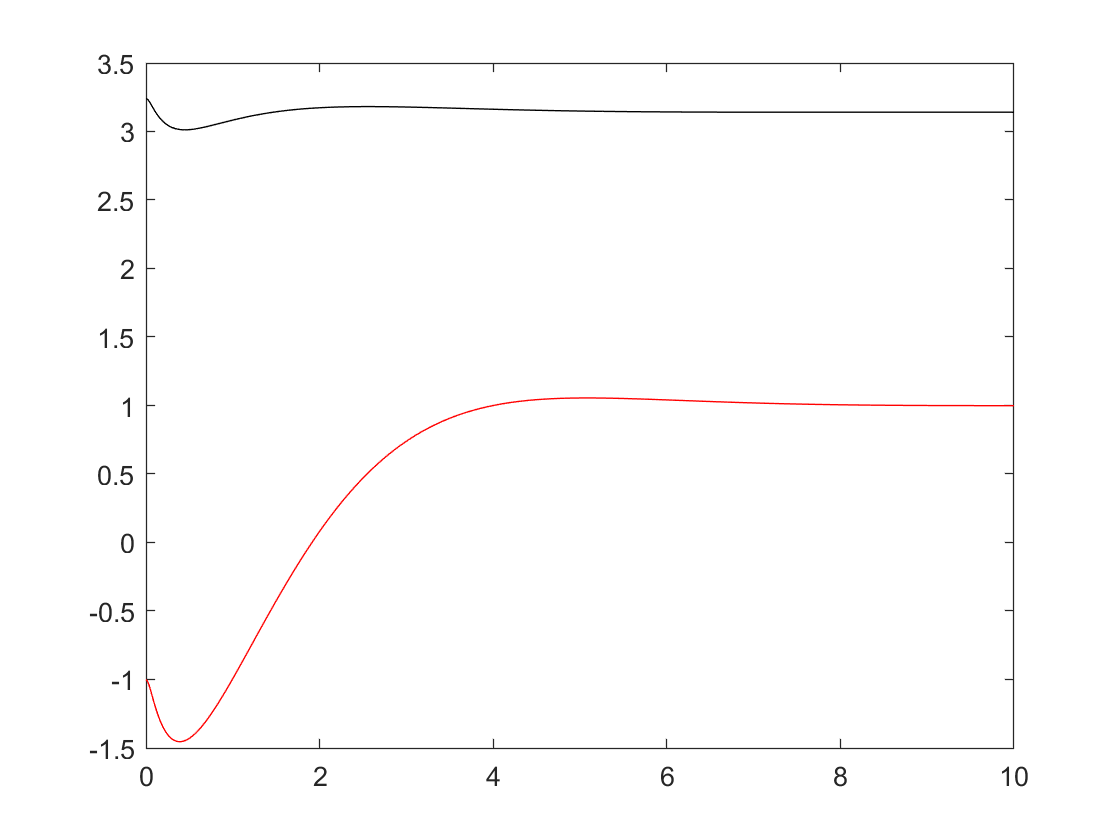

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;

for i = 2:(t_total/dt+1)
    [t,xtemp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,u(xlast)),(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

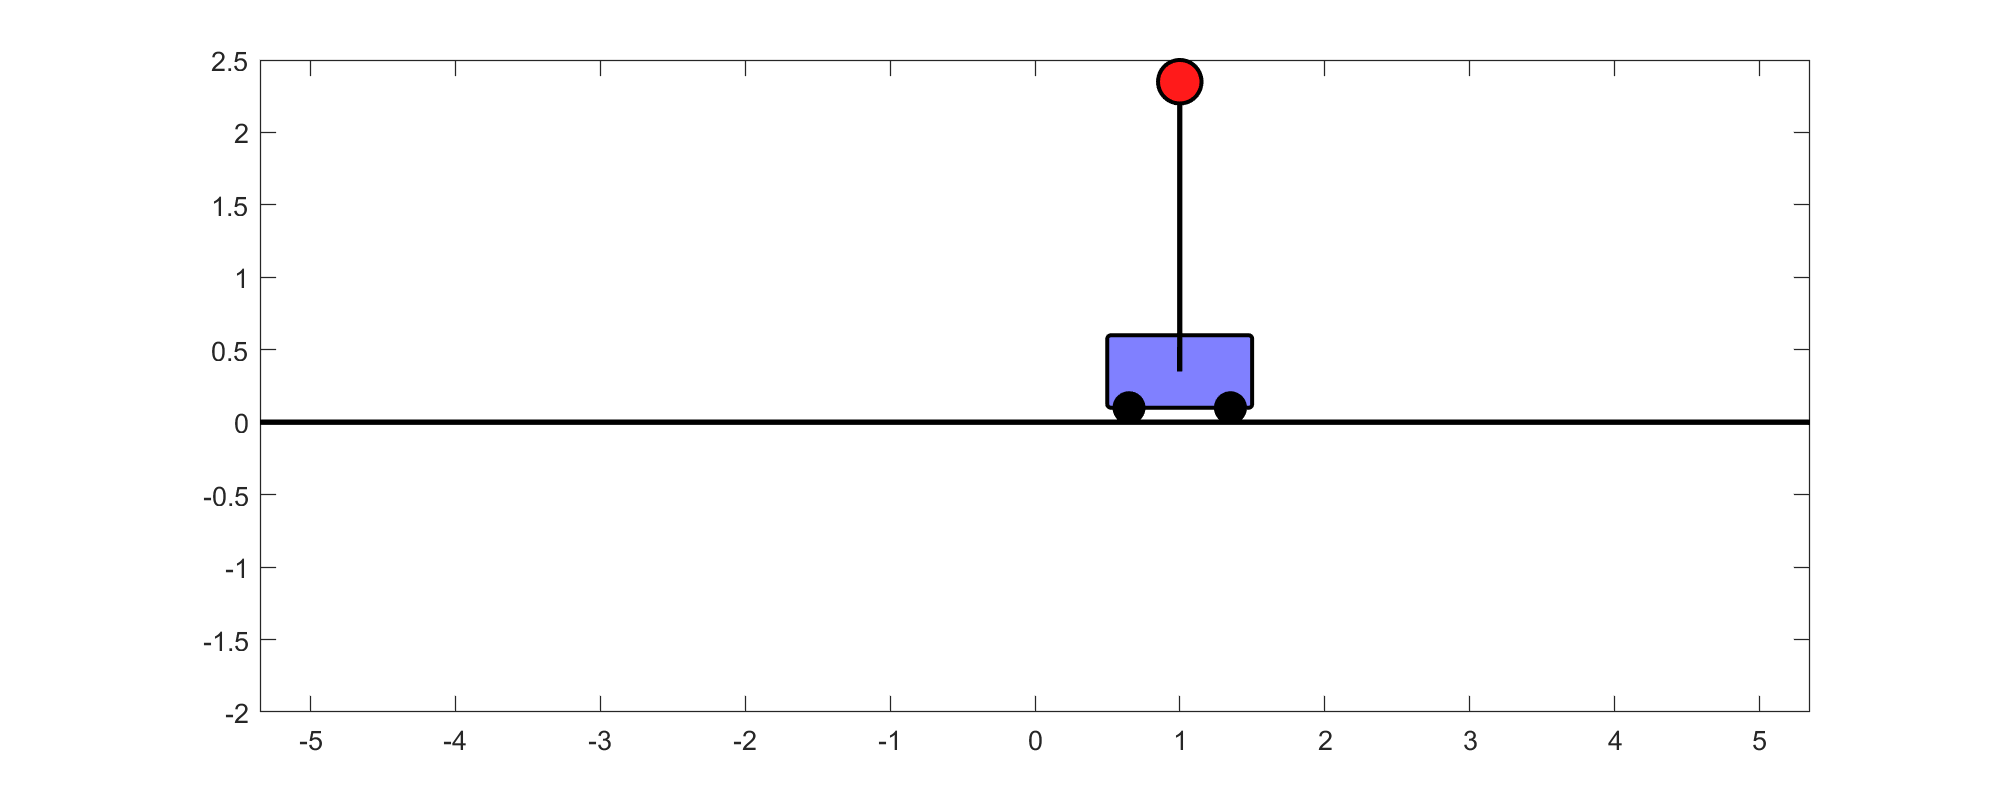


for k=1:10:length(t_span)
    drawpend(x(k,:),m,M,L);
end

# Simulation - Attack, No recovery

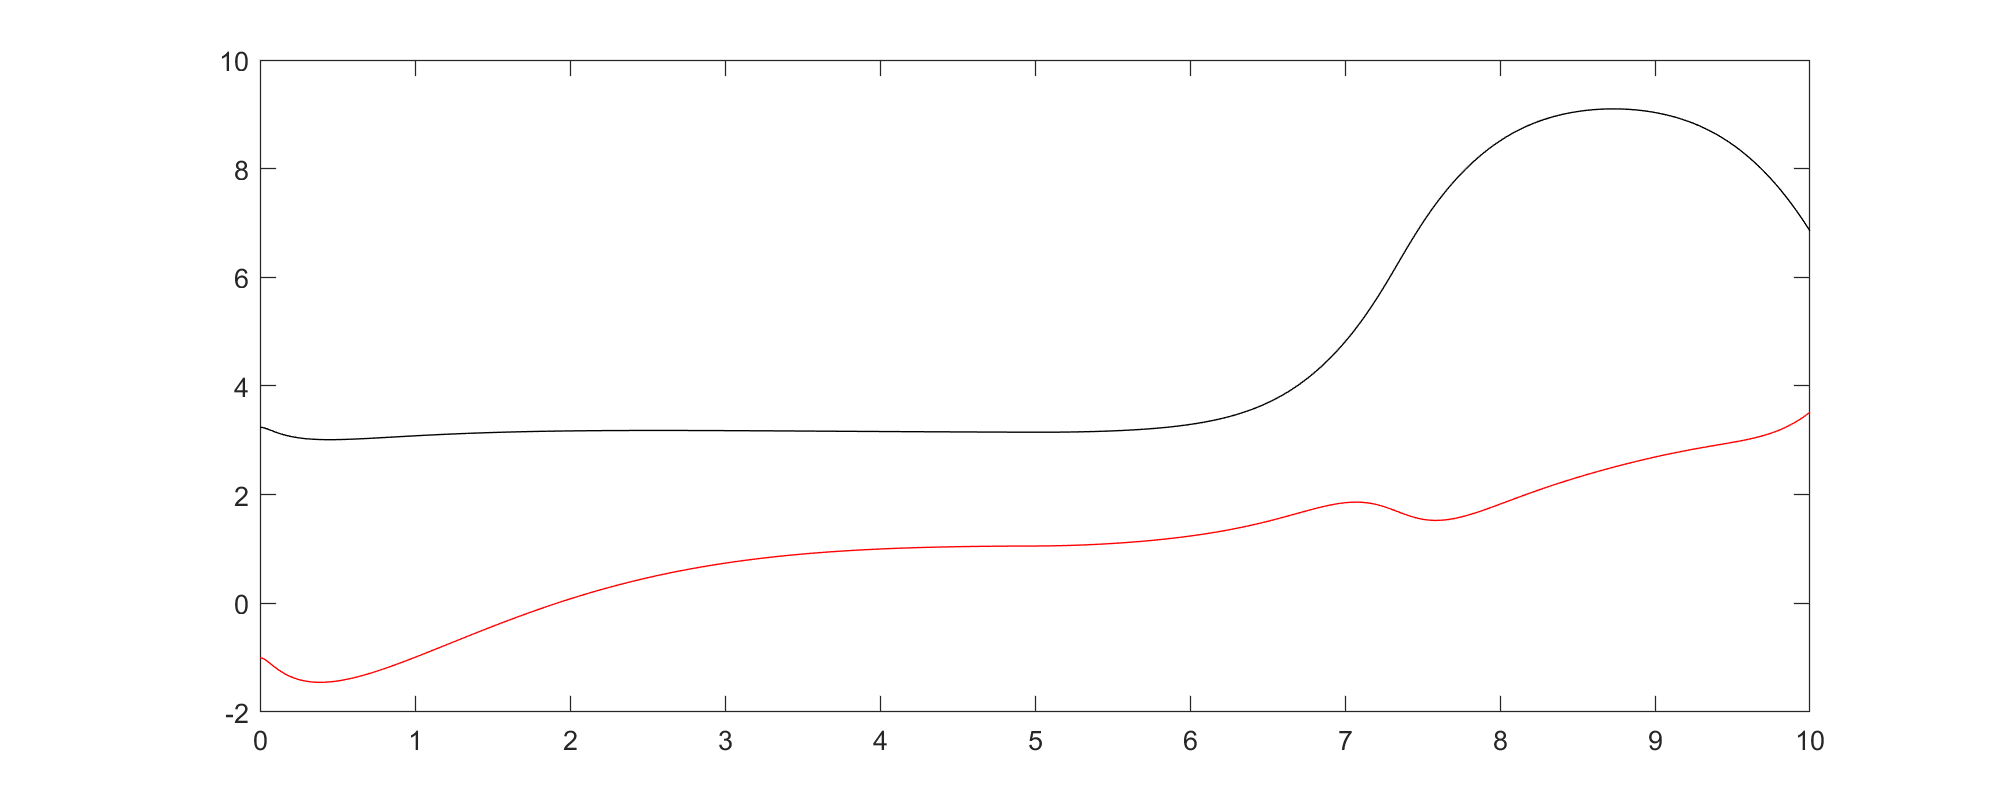

x = zeros(size(t_span,2),size(x0,1));  % actual state
x_dirty = zeros(size(t_span,2),size(x0,1));  % measurement state

x(1,:) = x0';
x_dirty(1,:) = x0';
xlast = x0;
x_dirty_last = x0;
attack_type = "force";

for i = 2:(t_total/dt+1)
    if i > t_attack/dt
        x_dirty_last = attack(attack_type, x_dirty_last);
    end
    input = u(x_dirty_last);
    [~,xtemp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    
    [~,x_dirty_temp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),x_dirty_last);
    x_dirty_last = x_dirty_temp(end,:);
    x_dirty(i,:) = x_dirty_last;
    x_dirty_last = x_dirty_last';
end

plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

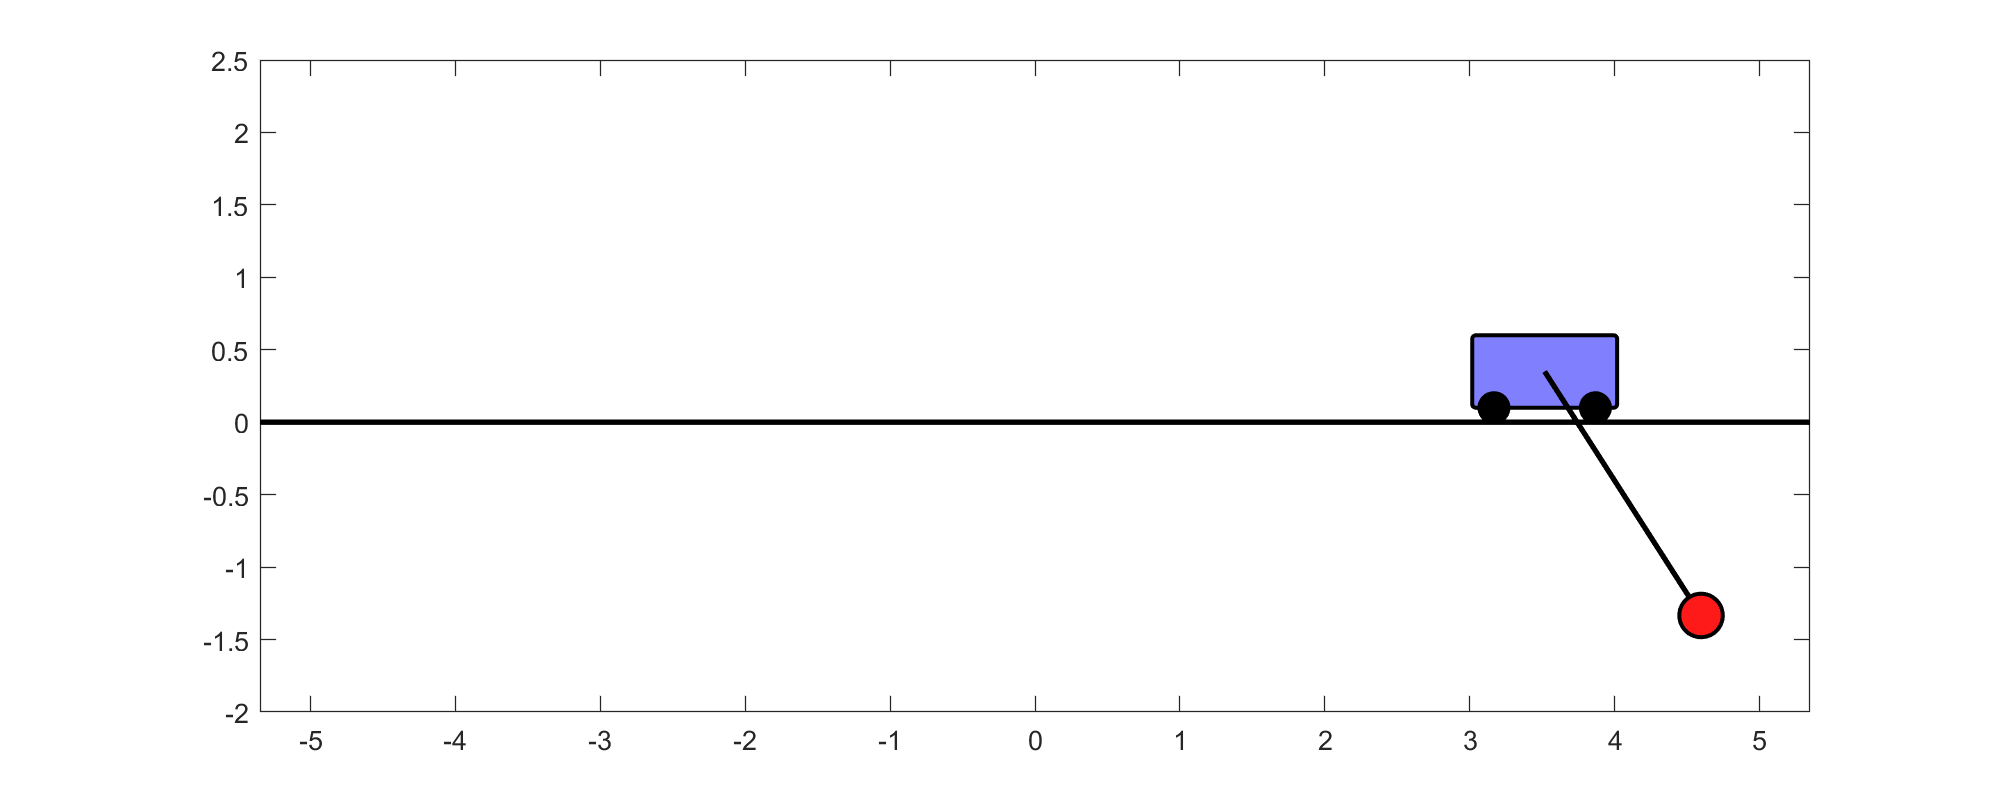


for k=1:10:length(t_span)
    drawpend(x(k,:),m,M,L);
end

# Simulation - Attack, With recovery

x = zeros(size(t_span,2),size(x0,1));  % actual state
x_dirty = zeros(size(t_span,2),size(x0,1));  % measurement state

x(1,:) = x0';
x_dirty(1,:) = x0';
xlast = x0;
x_dirty_last = x0;

detected = 0;
reset = 0;
control = u;
attack_type = "force";

for i = 2:(t_total/dt+1)
    % detection here
    if i > (t_attack+1)/dt
        detected = 1;
    end
    % end of detection 
   
    if i > t_attack/dt 
        if detected
            % recovery here
            if ~reset
                control = u;
                x_dirty_last = xlast;
                reset = 1;
                disp('recoverd!');
            end
            % end of recovery
        else
            x_dirty_last = attack(attack_type, x_dirty_last);
        end
    end 
    
    input = control(x_dirty_last);
    [~,xtemp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    
    [~,x_dirty_temp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),x_dirty_last);
    x_dirty_last = x_dirty_temp(end,:);
    x_dirty(i,:) = x_dirty_last;
    x_dirty_last = x_dirty_last';
    
end

recoverd!


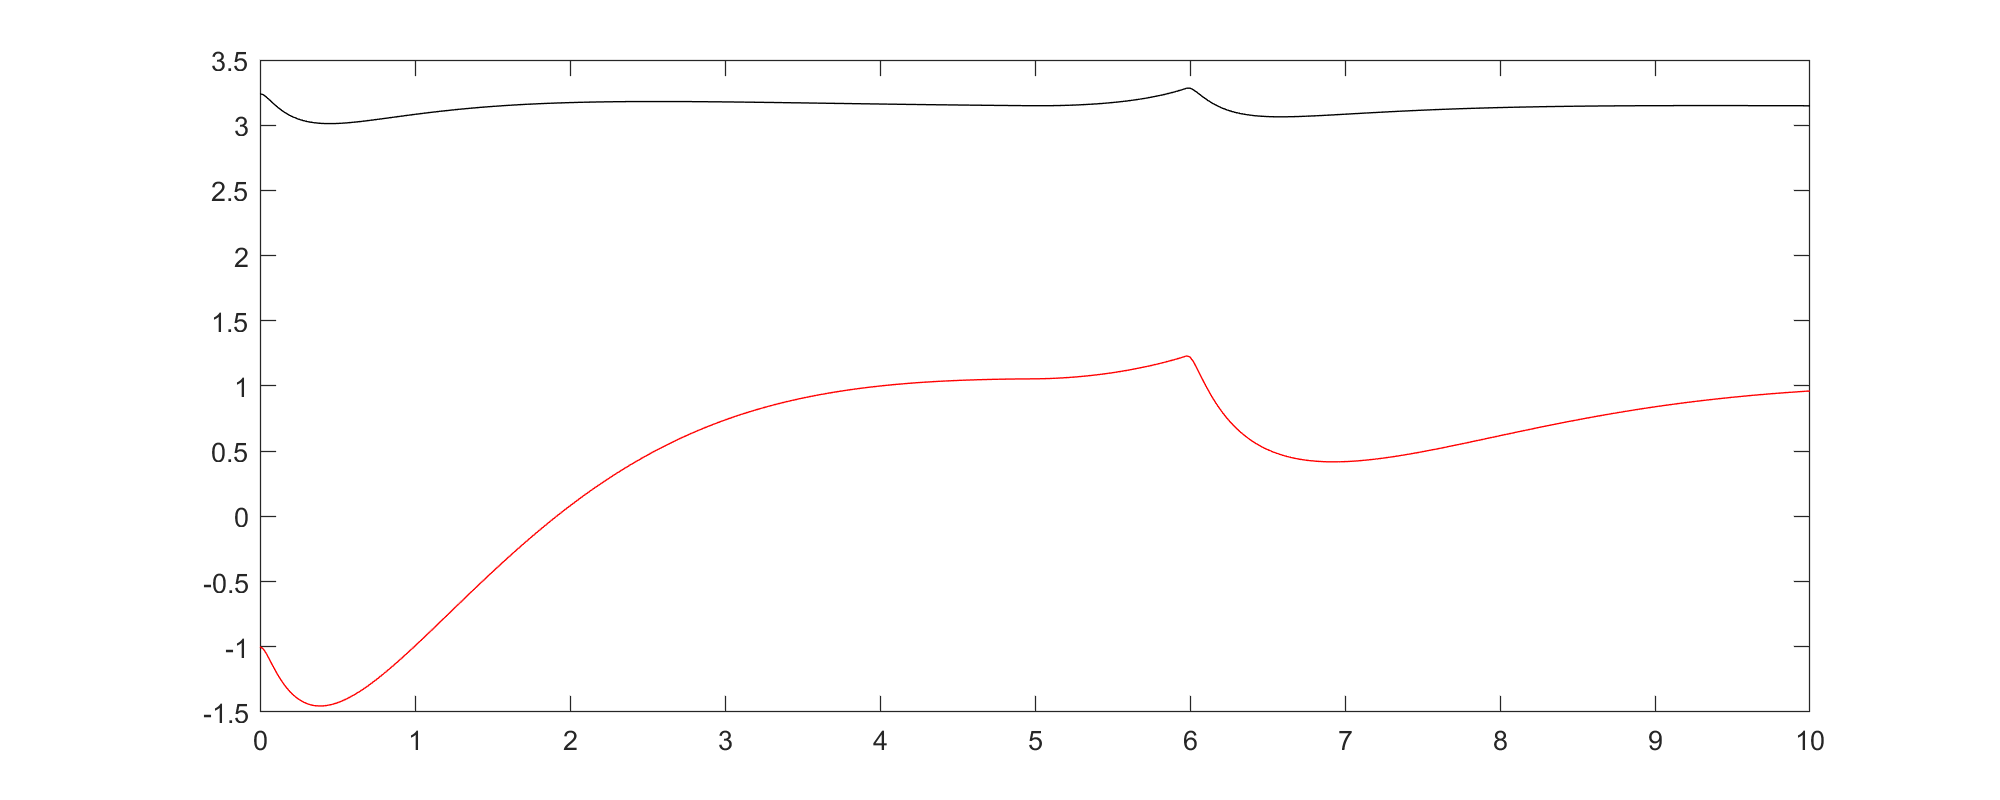


plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

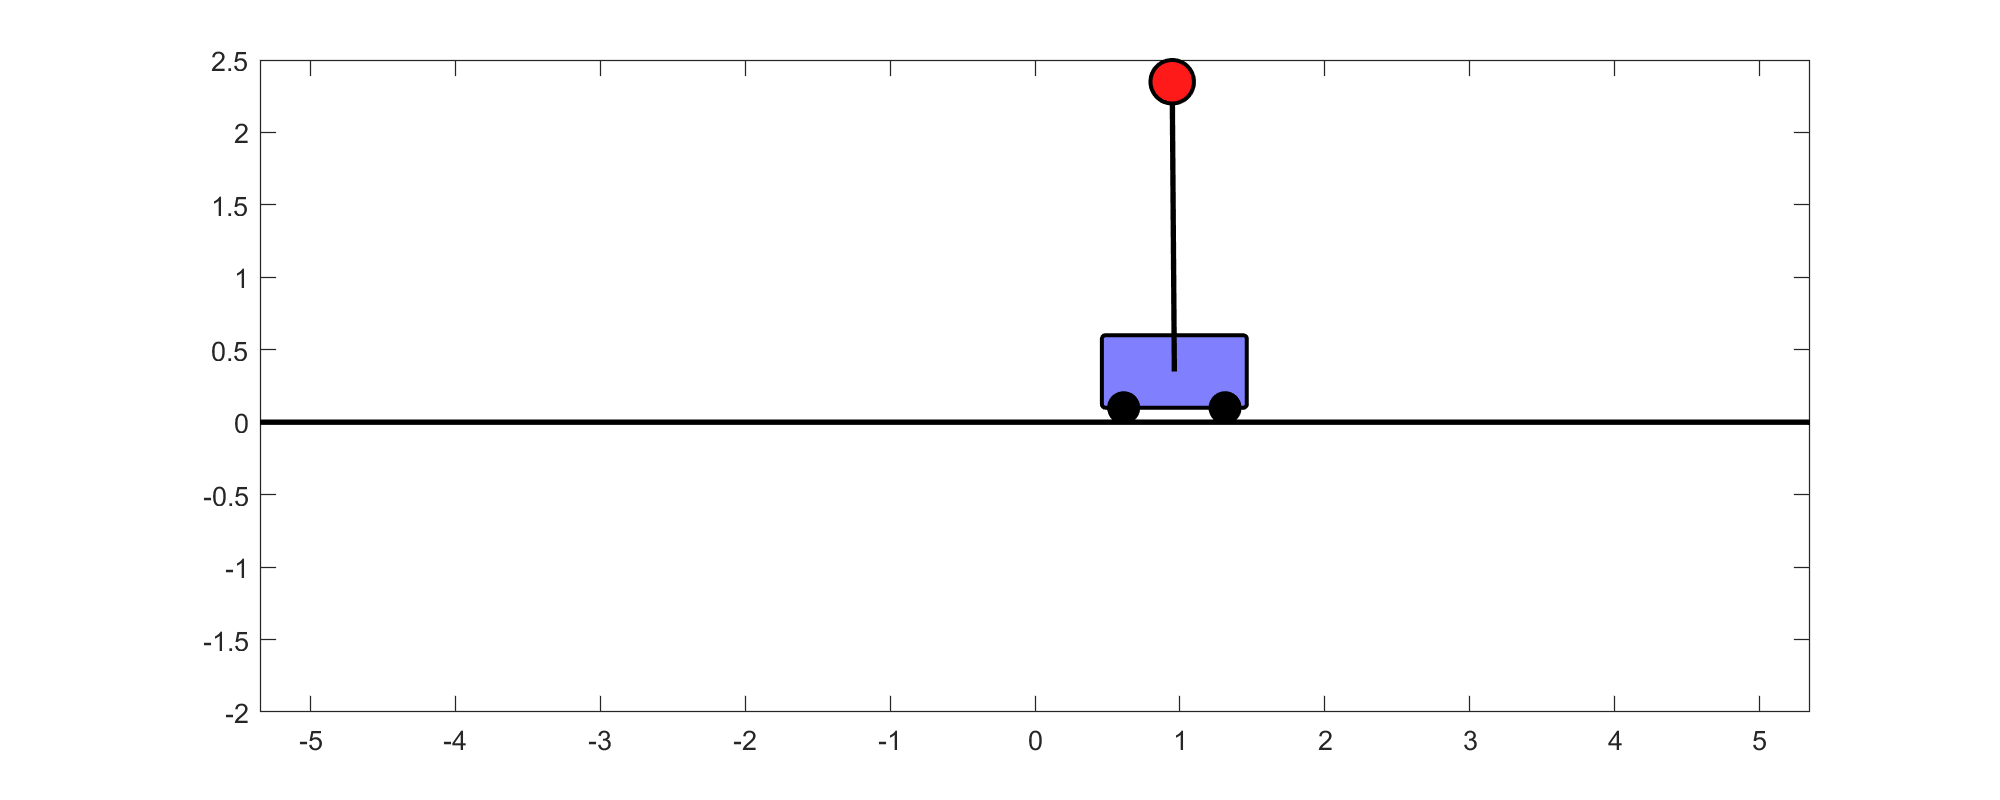


for k=1:10:length(t_span)
    drawpend(x(k,:),m,M,L);
end